%Set up the workspace
clc;clear
startup;

## Simulation for phase screen 0-pi with receive 1.

Simulation parameters

% Define the simulation window
sim_reg = SimulationRegion(5e-2, 5e-2, 512, 512);
% Define channel properties
L = 7;
Cn2=1e-10;
D_0=1000; % Outer scale   [m]
d_0=1e-6; %  Inner scale  [m]
corr_coeff = 0.0001;
% Simulation parameters
n_screen=1; % Number of phase screen
n_iter = 1; % Iteration number

% Transmitter properties 
w_in = 1e-2; % Transmitter spot size


% Generate a normalized gaussian beam as input


U_in= exp(-(sim_reg.X.^2 + sim_reg.Y.^2)/(w_in^2)); % normalized gaussian beam used as input of the free channel
U_in = U_in/sqrt(int2(abs(U_in).^2, sim_reg));
xc = 0;
yc = 0; % initial coordinates of aperture
xcount = 0; %counter to cicle through positions of the aperture
d = 50e-6;
c_free = zeros(9,1);% Preallocate memory
c_turbulent = zeros(n_iter,9);


%Simulate turbulent propagation

for k = 1:9
% Receiver properties
    S = 2e-2;
    
    receiver = Receiver1(sim_reg);
    receiver.w0 = 3e-3/2;
    receiver.center = [xc, yc]; 
    

    U_out = free_prop(U_in, sim_reg, L);
    c = overlap(receiver.U ,U_out(:, :), sim_reg);
    c_free(k) = c;

    if xcount<2
        xc=xc+d;
        xcount=xcount+1;

    else
        xc=0;
        xcount=0;
        yc=yc+d;
    end

    U_out = zeros(sim_reg.N_x, sim_reg.N_y, n_iter);
    phase_no_turb = angle(free_prop(U_in, sim_reg, L));
    U_rec = receiver.U.*exp(1i*phase_no_turb);
    phase_screen_old=zeros(sim_reg.N_x, sim_reg.N_y);

  
    % propagation through a turbulent medium
    [U_out(:, :), ] = turbulent_prop_new(U_rec, sim_reg, L, Cn2, D_0, d_0, n_screen, phase_screen_old, corr_coeff);
    c_turbulent(k) = overlap(receiver.U ,U_out(:, :), sim_reg);
    
end


%Figure orignal signal and output signal.

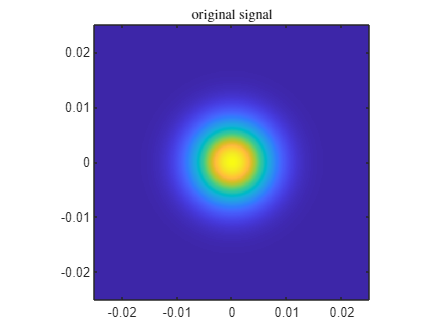


I1=abs(U_in.^2); %src irradiance
figure(1)
imagesc(sim_reg.x,sim_reg.y,I1);
axis square; axis xy;
title('original signal')

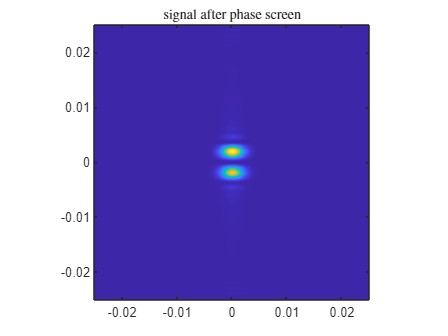


I2=abs(U_out.^2); %src irradiance
figure(2)
imagesc(sim_reg.x,sim_reg.y,I2);
axis square; axis xy;
title('signal after phase screen')

%Calculate  the orthogonality.

c_free=conj(c_free);
c_free=c_free/norm(c_free);
c_turbulent=c_turbulent/norm(c_turbulent);
orthogonality=-dot(c_free,c_turbulent);


## Simulation for phase screen for receive 9.

%%Simulation parameters

% Define the simulation window
sim_reg = SimulationRegion(5e-2, 5e-2, 512, 512);
% Define channel properties
L = 7;
Cn2=1e-10;
D_0=1000; % Outer scale   [m]
d_0=1e-6; %  Inner scale  [m]
corr_coeff = 0.0001;
% Simulation parameters
n_screen=1; % Number of phase screen
n_iter = 1; % Iteration number

% Transmitter properties 
w_in = 1e-2; % Transmitter spot size


% Generate a normalized gaussian beam as input


U_in= exp(-(sim_reg.X.^2 + sim_reg.Y.^2)/(w_in^2)); % normalized gaussian beam used as input of the free channel
U_in = U_in/sqrt(int2(abs(U_in).^2, sim_reg));


%Simulate turbulent propagation

disp = [5e-6, 5e-6;3e-6, 3e-6;2e-6, 2e-6;5e-6, 5e-6;5e-6, 5e-6;5e-6, 5e-6;5e-6, 5e-6;5e-6, 5e-6;5e-6, 5e-6];
receiver = Receiver9(sim_reg,disp);
U_out = zeros(sim_reg.N_x, sim_reg.N_y, n_iter);
phase_no_turb = angle(free_prop(U_in, sim_reg, L));
U_rec = receiver.U.*exp(1i*phase_no_turb);
phase_screen = zeros(sim_reg.N_x, sim_reg.N_y, n_iter);
phase_screen_old=zeros(sim_reg.N_x, sim_reg.N_y);

[U_out(:, :), phase_screen_old] = turbulent_prop_new(U_rec, sim_reg, L, Cn2, D_0, d_0, n_screen, phase_screen_old, corr_coeff);
phase_screen(:, :) = phase_screen_old;
% overlap between the incoming and the receiver's fields


%Figure for input and output signal

I1=abs(U_in.^2); %src irradiance
figure(1)
imagesc(sim_reg.x,sim_reg.y,I1);
axis square; axis xy;
title('original signal')

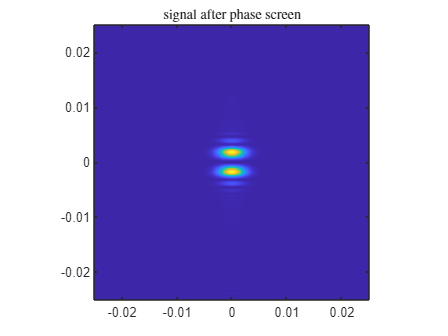


I2=abs(U_out.^2); %src irradiance
figure(2)
imagesc(sim_reg.x,sim_reg.y,I2);
axis square; axis xy;
title('signal after phase screen')

## Simulation for one lens.


L1=25e-3; %side length
M=5000; %number of samples
dx1=L1/M; %src sample interval
x1=-L1/2:dx1:L1/2-dx1; %src coords
y1=x1;
sim_reg = SimulationRegion(L1, L1, M, M);

lambda=0.5*10^-6; %wavelength
z=2*250; %propagation dist (m)

w_in = 0.5e-3; % Transmitter spot size

wr = 25e-3;
zf=0.25;
r=0.0125;


Gaussian signal

u1= exp(-(sim_reg.X.^2 + sim_reg.Y.^2)/(w_in^2)); % normalized gaussian beam used as input of the free channel
u1 = u1/sqrt(int2(abs(u1).^2, sim_reg));

simulation lens

P=circle_window(x1,y1,r);
u1=P.*u1;
u1=focus(u1,L1,lambda,zf);
u2=propIR(u1,L1,lambda,10*zf);

Figure input and output signals

I1=abs(u1.^2); %src irradiance
figure(1)
imagesc(x1,y1,I1);
axis square; axis xy;
% colormap('gray');  xlabel('x (m)'); ylabel('y (m)');
title('original signal');

I2=abs(u2.^2);
figure(4) %display obs irrad
imagesc(x1,y1,I2);
axis square; axis xy;
% colormap('gray'); xlabel('x (m)'); ylabel('y (m)');
title('signal at the plane which is 10*f far from lens.');


## Simulation for two lens

%Initialization for variables

L1=25e-3; %side length
M=5000; %number of samples
dx1=L1/M; %src sample interval
x1=-L1/2:dx1:L1/2-dx1; %src coords
y1=x1;
sim_reg = SimulationRegion(L1, L1, M, M);

lambda=0.5*10^-6; %wavelength
w=0.01; %source half width (m)
w_in = 2.5e-2; % Transmitter spot size

L = 10;%Transmition length of turbulent propagation.
Cn2=1e-10;
D_0=1000; % Outer scale   [m]
d_0=1e-6; %  Inner scale  [m]
corr_coeff = 0.1;
% Simulation parameters
n_screen=1; % Number of phase screen

zf=0.25; %focus length of lens
r=0.0125; %radius of lens
P=circle_window(x1,y1,r); %window for lens.


%Intialize the input signal for gaussian 


% Generate a normalized gaussian beam as input
u1= exp(-(sim_reg.X.^2 + sim_reg.Y.^2)/(w_in^2)); % normalized gaussian beam used as input of the free channel
u1 = u1/sqrt(int2(abs(u1).^2, sim_reg));


%Create random signal using MVK turbulent propagation.


phase_screen_old=zeros(sim_reg.N_x, sim_reg.N_y);
[u1(:, :), ] = turbulent_prop(u1, sim_reg, L, Cn2, D_0, d_0, n_screen, phase_screen_old, corr_coeff);
% phase_screen(:, :) = phase_screen_old;

u1=P.*u1;
I1=abs(u1.^2); %src irradiance


%Simuation of lens


u1=focus(u1,L1,lambda,zf); %phase screen for first lens
u2=propTF(u1,L1,lambda,2*zf); %signal at the second lens plane
u2=P.*u2;
u3=focus(u2,L1,lambda,zf); %phase screen for second lens
u4=propTF(u3,L1,lambda,3*zf); %signal after the second lens plane.


%Figure for input and output signal.


x2=x1; %obs coords
y2=y1;

figure(1)
imagesc(x1,y1,I1);
axis square; axis xy;
title('original signal');

I4=abs(u4.^2);
figure(3) %display obs irrad
imagesc(x1,y1,I4);
axis square; axis xy;
title('final signal after the second lens');



## Orthogonality for HG00 AND HG01

%Simulation parameters
% Define the simulation window
sim_reg = SimulationRegion(5e-2, 5e-2, 512, 512);
% Define channel properties
L = 7;

% Simulation parameter
n_iter = 1; % Iteration number

% Transmitter properties 
w_in = 1e-2; % Transmitter spot size

% Generate a normalized gaussian beam as input

Initialize input signals to the HG00 and HG01.

U_HG00= exp(-(sim_reg.X.^2 + sim_reg.Y.^2)/(w_in^2)); % HG00
U_HG00 = U_HG00/sqrt(int2(abs(U_HG00).^2, sim_reg)); %normalized HG00

U_HG01= 2*sim_reg.Y.*exp(-(sim_reg.X.^2 + sim_reg.Y.^2)/(w_in^2)); % HG01
U_HG01 = U_HG01/sqrt(int2(abs(U_HG01).^2, sim_reg)); %normalized HG01

Figure HG00 and HG01 signal.

I1=abs(U_HG00.^2); %src irradiance
figure(1)
imagesc(sim_reg.x,sim_reg.y,I1);
axis square; axis xy;
title('HG00 signal')


I2=abs(U_HG01.^2); %src irradiance
figure(2)
imagesc(sim_reg.x,sim_reg.y,I2);
axis square; axis xy;
title('HG01 signal')


Get the output signals for HG00 and HG01 after free propagation and calculate the orthogonality between them.

xc = 0;
yc = 0; % initial coordinates of aperture
xcount = 0; %counter to cicle through positions of the aperture
d = 50e-6;
c_free = zeros(9,1);% Preallocate memory
c_turbulent = zeros(n_iter,9);


for k = 1:9
% Receiver properties
    S = 2e-2;
    
    receiver = Receiver1(sim_reg);
    receiver.w0 = 3e-3/2;
    receiver.center = [xc, yc]; 
    

    U_out = free_prop(U_HG00, sim_reg, L);
    c = overlap(receiver.U ,U_out(:, :), sim_reg);
    c_free(k) = c;
        
    U_out = free_prop(U_HG01, sim_reg, L);
    c = overlap(receiver.U ,U_out(:, :), sim_reg);
    c_turbulent(k) = c;

    if xcount<2
        xc=xc+d;
        xcount=xcount+1;

    else
        xc=0;
        xcount=0;
        yc=yc+d;
    end
end

c_free=conj(c_free);
c_free=c_free/norm(c_free);
c_turbulent=c_turbulent/norm(c_turbulent);
orthogonality=-dot(c_free,c_turbulent);


## MVK Turbulent propagation for HG00 and HG01

%Simulation parameters
% Define the simulation window
sim_reg = SimulationRegion(5e-2, 5e-2, 512, 512);
% Define channel properties
L = 7;
Cn2=1e-10;
D_0=1000; % Outer scale   [m]
d_0=1e-6; %  Inner scale  [m]
corr_coeff = 0.0001;
% Simulation parameters
n_screen=1; % Number of phase screen

% Transmitter properties 
w_in = 1e-2; % Transmitter spot size


%Initialize input signals to the HG00 and HG01.


% Generate a normalized gaussian beam as input
U_HG00= exp(-(sim_reg.X.^2 + sim_reg.Y.^2)/(w_in^2)); % HG00
U_HG00 = U_HG00/sqrt(int2(abs(U_HG00).^2, sim_reg)); %normalized HG00

U_HG01= 2*sim_reg.Y.*exp(-(sim_reg.X.^2 + sim_reg.Y.^2)/(w_in^2)); % HG01
U_HG01 = U_HG01/sqrt(int2(abs(U_HG01).^2, sim_reg)); %normalized HG01


%Figure for HG00 and HG01

I1=abs(U_HG00.^2); %src irradiance
figure(1)
imagesc(sim_reg.x,sim_reg.y,I1);
axis square; axis xy;
title('HG00 signal')

I2=abs(U_HG01.^2); %src irradiance
figure(2)
imagesc(sim_reg.x,sim_reg.y,I2);
axis square; axis xy;
title('HG01 signal')


%Propagate HG00 and HG01 through MVK.

phase_screen_old=zeros(sim_reg.N_x, sim_reg.N_y);
[UOUT_HG00(:, :), ] = turbulent_prop(U_HG00, sim_reg, L, Cn2, D_0, d_0, n_screen, phase_screen_old, corr_coeff);

phase_screen_old=zeros(sim_reg.N_x, sim_reg.N_y);
[UOUT_HG01(:, :), ] = turbulent_prop(U_HG01, sim_reg, L, Cn2, D_0, d_0, n_screen, phase_screen_old, corr_coeff);


%Figure output signals for HG00 and HG01

I3=abs(UOUT_HG00.^2); %src irradiance
figure(3)
imagesc(sim_reg.x,sim_reg.y,I3);
axis square; axis xy;
title('OUTPUT FOR HG00')

I4=abs(UOUT_HG01.^2); %src irradiance
figure(4)
imagesc(sim_reg.x,sim_reg.y,I4);
axis square; axis xy;
title('HG01 signal');

## **Tilt test**

%Simulation parameters
L1=0.5; %side length
M=2000; %number of samples
dx1=L1/M; %src sample interval
x1=-L1/2:dx1:L1/2-dx1; %src coords
y1=x1;
lambda=0.5*10^-6; %wavelength
z=2000; %propagation dist (m)

w_in = 1e-2;

Initialize HG00 SIGNAL with width of w_in

[X1,Y1]=meshgrid(x1,y1);
u1= exp(-(X1.^2 + Y1.^2)/(w_in^2)); % normalized gaussian beam used as input of the free channel
I1=abs(u1.^2); %src irradiance

%Plot irradiance of HG00

figure(1)
imagesc(x1,y1,I1);
axis square; axis xy;
xlabel('x (m)'); ylabel('y (m)');
title('z= 0 m')
%PARAMETERS FOR TILT
deg=pi/180;
alpha=5.0e-5; %rad
theta=45*deg;

%Tilt and propagation

[u1]=tilt(u1,L1,lambda,alpha,theta);
% u2=propTF(u1,L1,lambda,z); %propagation
u2=propIR(u1,L1,lambda,z); %propagation
x2=x1; %obs coords
y2=y1;
I2=abs(u2.^2); %obs irrad
figure(2) %display obs irrad
imagesc(x2,y2,nthroot(I2,3));%stretch image contrast
axis square; axis xy;
% colormap('gray');
xlabel('x (m)'); ylabel('y (m)');
title(['z= ',num2str(z),' m']);
 %irradiance profile
figure(3) 
plot(x2,I2(M/2+1,:));
xlabel('x (m)'); ylabel('Irradiance');
title(['z= ',num2str(z),' m']);
%plot obs field mag
figure(4) 
plot(x2,abs(u2(M/2+1,:)));
xlabel('x (m)'); ylabel('Magnitude');
title(['z= ',num2str(z),' m']);
%plot obs field phase
figure(5) 
plot(x2,unwrap(angle(u2(M/2+1,:))));
xlabel('x (m)'); ylabel('Phase (rad)');
title(['z= ',num2str(z),' m']);

## Simulation for two HG00 signal

L1=0.0005; %side length
M=8000; %number of samples
dx1=L1/M; %src sample interval
x1=-L1/2:dx1:L1/2-dx1; %src coords
y1=x1;
lambda=0.5*10^-6; %wavelength

z=1; %propagation dist (m)

%parameters for HG00 input signals
w_in = 1e-5;        %width of HG00 signal
x1c = 1.5e-5;         %x-axis position of center of first HG00 signal
y1c = 0;            %y-axis position of center of first HG00 signal
x2c = -1e-5;        %x-axis position of center of second HG00 signal
y2c = 0;            %y-axis position of center of second HG00 signal


%generate two HG00 input signals

[X1,Y1]=meshgrid(x1,y1);
u1 =  exp(-((X1-x1c).^2 + (Y1-y1c).^2)/(w_in^2)); %first HG00 signal
u2 =  exp(-((X1-x2c).^2 + (Y1-y2c).^2)/(w_in^2)); %second HG00 signal

uin = u1 + u2;
I1=abs(uin.^2); %src irradiance

%Plot input signal 

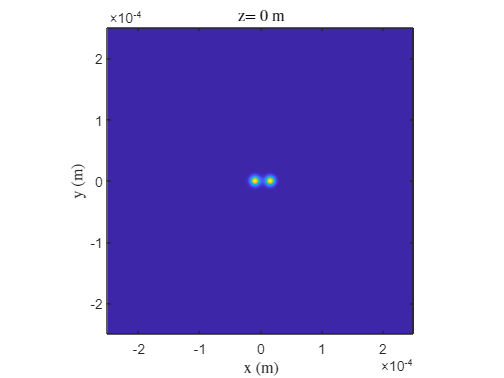

figure(1)
imagesc(x1,y1,I1);
axis square; axis xy;
xlabel('x (m)'); ylabel('y (m)');
title('z= 0 m')


uout=propTF(uin,L1,lambda,z); %propagation
%u2=propIR(u1,L1,lambda,z); %propagation
x2=x1; %obs coords
y2=y1;
I2=abs(uout.^2); %obs irrad


%Plot output signal

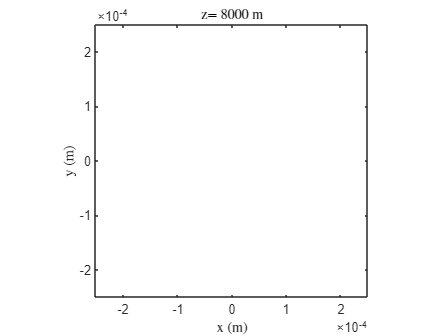

figure(2) %display obs irrad
imagesc(x2,y2,nthroot(I2,3));%stretch image contrast
axis square; axis xy;
xlabel('x (m)'); ylabel('y (m)');
title(['z= ',num2str(z),' m']);

## Simulation for nine HG00 signals

L1=0.5; %side length
M=2000; %number of samples
dx1=L1/M; %src sample interval
x1=-L1/2:dx1:L1/2-dx1; %src coords
y1=x1;

z=2000; %propagation dist (m)

%parameters for HG00 input signals
w_in = 1e-2;        %width of HG00 signal
r = 4e-2;

%generate two HG00 input signals

[X1,Y1]=meshgrid(x1,y1);

disp_v = r;
uin =  exp(-((X1-r).^2 + Y1.^2)/(w_in^2));
for i = 1:8
    disp_v = disp_v * (cos(2*pi/9)+1j*sin(2*pi/9));
    xc = real(disp_v);
    yc = imag(disp_v);
    uin = uin +  exp(-((X1-xc).^2 + (Y1-yc).^2)/(w_in^2));
end

I1=abs(uin.^2); %src irradiance


%Plot input signal 

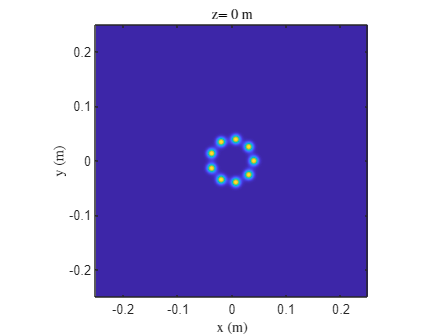

figure(1)
imagesc(x1,y1,I1);
axis square; axis xy;
xlabel('x (m)'); ylabel('y (m)');
title('z= 0 m');

% uout=propTF(uin,L1,lambda,z); %propagation
u2=propIR(u1,L1,lambda,z); %propagation
x2=x1; %obs coords
y2=y1;
I2=abs(uout.^2); %obs irrad


%Plot output signal

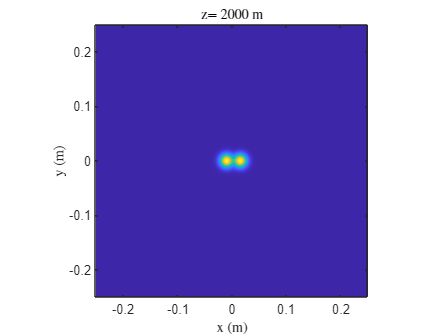

figure(2) %display obs irrad
imagesc(x2,y2,nthroot(I2,3));%stretch image contrast
axis square; axis xy;
xlabel('x (m)'); ylabel('y (m)');
title(['z= ',num2str(z),' m']);

## Simulation for nine HG00 signals in Square

L1=0.0005; %side length
M=2000; %number of samples
dx1=L1/M; %src sample interval
x1=-L1/2:dx1:L1/2-dx1; %src coords
y1=x1;
lambda=0.5*10^-6; %wavelength
k=2*pi/lambda; %wavenumber
w=0.051; %source half width (m)
z=8000; %propagation dist (m)

%parameters for HG00 input signals
w_in = 1e-5;        %width of HG00 signal
r = 2e-5;

%generate two HG00 input signals

[X1,Y1]=meshgrid(x1,y1);

uin =  zeros(length(X1),length(Y1));
for i = -1:1
    for j = -1:1
        xc = r*i;
        yc = r*j;
        uin = uin +  exp(-((X1-xc).^2 + (Y1-yc).^2)/(w_in^2));
    end
end

I1=abs(uin.^2); %src irradiance


%Plot input signal 

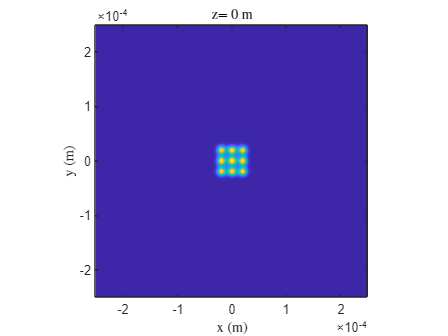

figure(1)
imagesc(x1,y1,I1);
axis square; axis xy;
xlabel('x (m)'); ylabel('y (m)');
title('z= 0 m')


uout=propTF(uin,L1,lambda,z); %propagation
%u2=propIR(u1,L1,lambda,z); %propagation
x2=x1; %obs coords
y2=y1;
I2=abs(uout.^2); %obs irrad


%Plot output signal

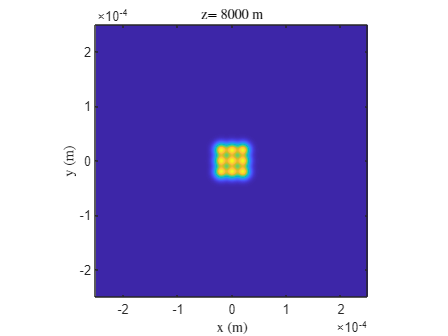

figure(2) %display obs irrad
imagesc(x2,y2,nthroot(I2,3));%stretch image contrast
axis square; axis xy;
xlabel('x (m)'); ylabel('y (m)');
title(['z= ',num2str(z),' m']);